#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

DAE     = WinxDAE( false );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

T     = 180;
DT    = 0.001;

s = 0;
theta1 =0;
theta2 = 0.3912390397;   %theta2 =2.750353614;
theta4 = 0.006780333643;   %theta4 = 3.134812320;
theta5 = 0;
theta6 = 0;
s__dot =0;
theta1__dot = 0;
theta2__dot = 0;
theta4__dot =0;
theta5__dot = 0;
theta6__dot = 0;
p0    = [ s, theta1, theta2, theta4, theta5, theta6 ];
v0    = [ s__dot, theta1__dot, theta2__dot, theta4__dot, theta5__dot, theta6__dot ];

#### Advance the DAE (using not stabilized index-1 DAE)

tt  = 0:DT:T;
[p, v]  = solver.advance_simple( tt,  p0, v0 );

#### plot solution

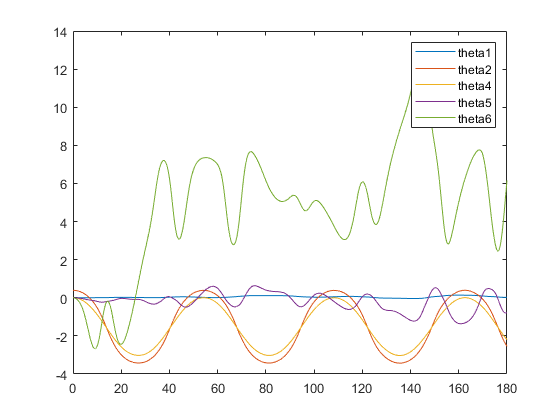

figure();
plot(tt,p(2,:),tt,p(3,:),tt,p(4,:),tt,p(5,:),tt,p(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

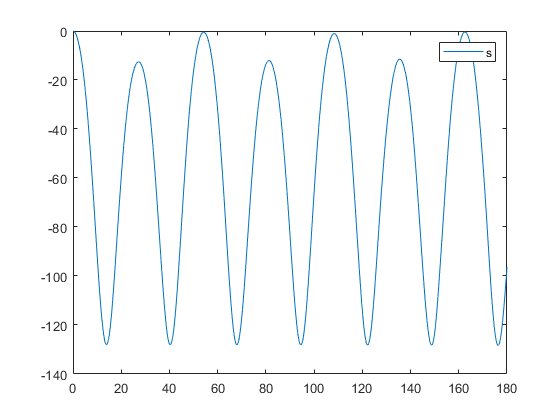

plot(tt,p(1,:)); 
legend('s'); % s in another chart because the scale it's too different

#### Advance the DAE (using  stabilized index-1 DAE)

set parameter

eta   = 0.5;
omega = 4;

advance

tt  = 0:DT:T;
[p, v ] = solver.advance_Baumgarte( tt,  p0, v0, eta, omega );

#### plot solution

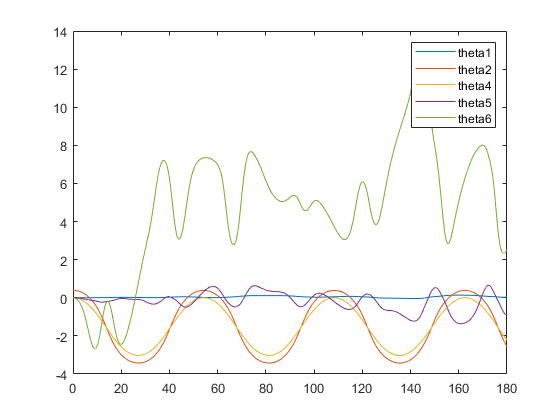

figure();
plot(tt,p(2,:),tt,p(3,:),tt,p(4,:),tt,p(5,:),tt,p(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

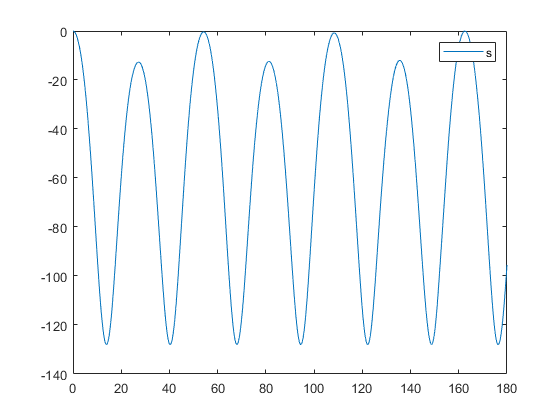

plot(tt,p(1,:)); 
legend('s'); % s in another chart because the scale it's too different